clear all;

## **Magnitude Bode Plot for Transfer Function, by polynomial coeffs**

fprintf('%50s','***************************')

                       ***************************

    
num = [2 2000];
den = [1 71 77 490];

G = tf(num,den)


G =
 
         2 s + 2000
  -------------------------
  s^3 + 71 s^2 + 77 s + 490
 
Continuous-time transfer function.



syms s
Zeros_factorized = factor(poly2sym(num));

% PFE, and getting the complex poles
[res,poles,~] = residue(num,den);
func_pfe = 0;
Poles = [];
omega_n = [];
zeta = [];
for i=1:length(res)
    if imag(poles(i)) == 0
        Poles = [Poles; poles(i)];
        func_pfe = func_pfe + res(i)/(s-poles(i));
    end
    if imag(poles(i)) ~= 0 && imag(poles(i-1)) == 0
        omega_n = [omega_n; abs(imag(poles(i)))];
        zeta = [zeta; abs(real(poles(i)))/omega_n(end)];
        func_pfe = func_pfe + ((res(i)*(s-poles(i+1)) + res(i+1)*(s-poles(i))) / ((s^2 - 2*s*real(poles(i)) + imag(poles(i))^2+real(poles(i))^2)));
    end
end

if has(Zeros_factorized(1),s)
    K = 1
else
    K = Zeros_factorized(1)
end

$$K = 2$$

K0 = evalfr(G, 0)

K0 = 4.0816

Zeros = zero(G)

Zeros = -1000

Poles

Poles = -70.0000

Poles_factorized = factor(poly2sym(den))

$$Poles\_factorized = \left(\begin{array}{cc} x+70 & x^{2}+x+7 \end{array}\right)$$

omega_n

omega_n = 2.5981

zeta

zeta = 0.1925

func_pfe

$$func\_pfe = \frac{0.3845}{s+70}-\frac{0.3845\,s-28.5330}{s^{2}+s+7}$$


vars = abs([Zeros; Poles; omega_n]);
w_range = [(min(vars))/100.0,100*(max(vars))+2];

fprintf('%50s','***************************')

                       ***************************

t = logspace(log10(w_range(1)),log10(w_range(2)),150);
y = db(K0)*ones(1,length(t));
p = ones(1,length(t));
hvsd = @(t,x) [0*(t <= x) + (t > x)];
hvsd_range = @(t,down,up) [0*(t <= down | t >= up) + (t>down & t<up)];

% Add zeros
for i=1:length(Zeros)
    if Zeros(i) == 0
        add = db(t);
        add_p = 90*ones(1,length(t));
    else
        mg = abs(Zeros(i));
        add = hvsd(t,mg).*db(t/mg);
        add_p = hvsd_range(t,mg/10,mg*10).*(45.*log10(t)-45*log10(mg/10)) + hvsd(t,mg*10)*90;
    end
    y = y + add;
    p = p + add_p;
end

% Add poles
for i=1:length(Poles)
    if Poles(i) == 0
        add = db(t);
    else
        mg = abs(Poles(i));
        add = hvsd(t,mg).*db(t/mg);
        add_p = hvsd_range(t,mg/10,mg*10).*(45.*log10(t)-45*log10(mg/10)) + hvsd(t,mg*10)*90;
    end
    y = y - add;
    p = p - add_p;
end

% Add complex poles
for i=1:length(omega_n)
    mg = abs(omega_n(i));
    add = 2.*hvsd(t,mg).*db(t/mg);
    add_p = 2.*hvsd_range(t,mg/10,mg*10).*(45.*log10(t)-45*log10(mg/10)) + hvsd(t,mg*10)*180;
    y = y - add;
    p = p - add_p;
    
    if zeta(i) < 1
        resonant = 1/(2*zeta(i)*sqrt(1-zeta(i)^2))
        [~,index] = min(abs(t-omega_n(i)));
        y(index) = y(index) + resonant;
    end
end

resonant = 2.6476

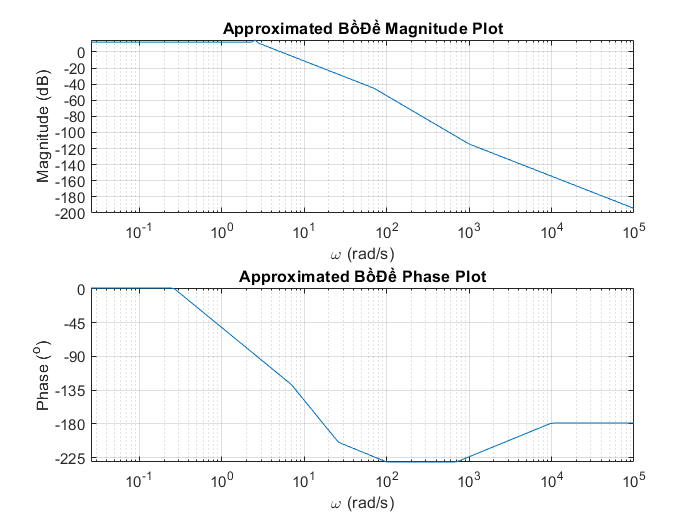


subplot(2,1,1);
semilogx(t,y)
ylabel('Magnitude (dB)')
xlabel('\omega (rad/s)')
xticks([1e-2,1e-1,1,10,1e2,1e3,1e4,1e5,1e6]);
yticks(-400:20:400);
xlim(w_range)
title('Approximated BồĐề Magnitude Plot')
grid on;

subplot(2,1,2);
semilogx(t,p)
ylabel('Phase (^o)')
xlabel('\omega (rad/s)')
xticks([1e-2,1e-1,1,10,1e2,1e3,1e4,1e5,1e6]);
yticks(-360:45:360);
xlim(w_range)
title('Approximated BồĐề Phase Plot')
grid on;


fprintf('%50s','***************************')

                       ***************************

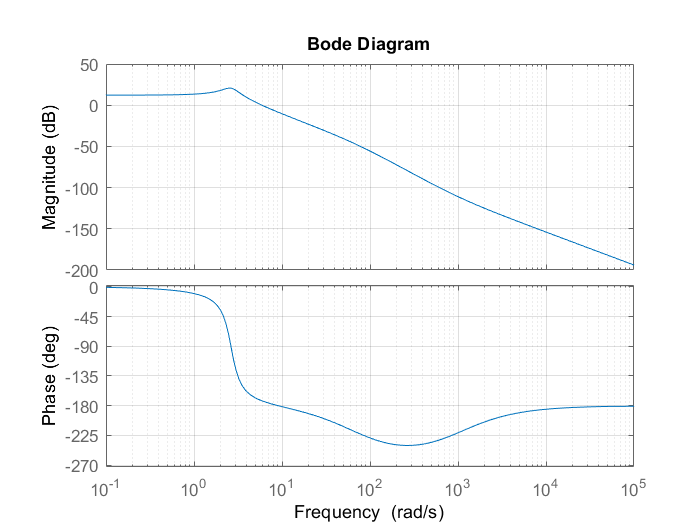

bode(G)
grid on;

fprintf('%50s','***************************')

                       ***************************

% T = 0:0.1:10;
% U = sin(T);
% lsim(G,U,T)

% step(G)
% impulse(G)

## Transfer function by poles and zeros

fprintf('%50s','***************************')

                       ***************************


zs = [3 5 7];
ps = [1 2 4];
num = poly(zs);
den = poly(ps);
G = tf(num,den)


G =
 
  s^3 - 15 s^2 + 71 s - 105
  -------------------------
   s^3 - 7 s^2 + 14 s - 8
 
Continuous-time transfer function.




fprintf('%50s','***************************')

                       ***************************

% bode(G)
% grid on;

% T = 0:0.1:10;
% U = sin(T);
% lsim(G,U,T)

% step(G)
% impulse(G)

fprintf('%50s','***************************')

                       ***************************


fprintf('%50s','***************************')

                       ***************************

function d = db(a)
    d = 20*log10(a);
end

function out = par(xs)
    sum = 0;
    prod = 1;
    for i=1:length(xs)
        sum = sum + 1/xs(i);
        %prod = prod*xs(i);
    end
    out = 1/sum;
end

function out = xpand(func)
    [num,den] = numden(func);    
    out = num/den;
end

function out = xpand_mat(func)
    sz = size(func);
    for i=1:sz(1)
        for j=1:sz(2)
            [nu,de] = numden(func(i,j));   
            out(i,j) = nu/de;            
        end
    end
end